# Metodo dei Minimi Quadrati

## Caso retta dei minimi quadrati

Partendo dai dati `(X, Y)` scrivo il sistema delle equazioni normali

Devo trovare la retta $\alpha x+\beta =L\left(x\right)$, con $\alpha$ e $\beta$ incognite.  

- Creo una matrice $\textrm{cond}\times \textrm{incog}$ con ogni elemento uguale a 0; 

- Inizializzo la matrice dei coefficienti `coeff`. 

- Ottengo il sistema $A\;c=Y$, con 𝑐 = [𝛼 𝛽]'  (vettore colonna incognite)

Nella teoria il sistema risulta sovradimenzionato, quindi dovrei calcolare il sistema di equazioni normali $A^T A\;c=A^T \;Y$.

Nella pratica si sfrutta l'operatore `\` che in matlab fornisce la soluzione rispetto ai minimi quadrati.

### Esempio codice

X = [1 2 3 4 1 2 1]' ;
Y = [7 2 9 2 8 1 6]' ;

coeff = zeros(length(X), 2);
coeff(:,1) = X;    % coefficienti di alpha 
coeff(:,2) = 1;    % coefficienti di beta

alphabeta = coeff \ Y;
alpha     = alphabeta(1);
beta      = alphabeta(2);
display([alpha, beta])

   -1.0000    7.0000



retta = @(x) alpha*x + beta;

absErr = abs(Y - retta(X))

absErr =     1.0000
    3.0000
    5.0000
    1.0000
    2.0000
    4.0000
         0


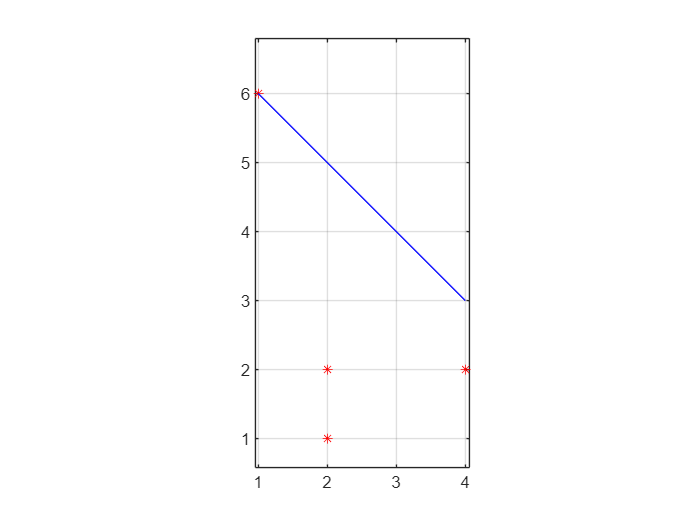


plot(X,Y,'*r')
    hold on, plot(1:4, retta(1:4), 'b'), hold off
    axis equal, grid on
    xlim([min(X)-1, max(X)+1])
    ylim([min(Y)-1, max(Y)+1])